# Observador

clear; close all; clc; 
addpath("data/");
addpath("data/tests");
load("DatosStepsVariables.mat");
load("DatosPID.mat");
theta_0 = 89;  % inicial
[sys, ~, ~, ~] = FoundTF(theta_0); 
load("data/TF.mat"); 

% Variables de estado 
A = sys.A; 
B = sys.B; 
C = sys.C; 
D = sys.D; 

% Matrices de ponderacion 
qx1 = 100; 
qx2 = 1000000; 
r = 0.001; 

Q = [qx1 0  ;0 qx2];
R = r; 

% Diseño de lqr 
[L, S, P] = lqr(A', C', Q, R); 
L = L'

L = 1.0e+04 *

    0.0401
    3.0303



Ahat = A-L*C;
Bhat = [B L];
Chat = eye(2);
Dhat = [0];

SysHat = ss(Ahat,Bhat,Chat,Dhat);
SysHat.StateName = {'thetaHat','omegaHat'};
SysHat.OutputName = {'thetaHat','omegaHat'};
SysHat.InputName = {'PWM','theta'};
Observer = c2d(SysHat,2.5e-3,'tustin'); % Implementacion en arduino

damp(SysHat)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -1.06e+02     1.00e+00       1.06e+02         9.41e-03    
 -2.98e+02     1.00e+00       2.98e+02         3.36e-03    


damp(Observer)

                                                                        
   Pole       Magnitude     Damping       Frequency      Time Constant  
                                        (rad/seconds)      (seconds)    
                                                                        
  7.66e-01     7.66e-01     1.00e+00       1.07e+02         9.36e-03    
  4.57e-01     4.57e-01     1.00e+00       3.13e+02         3.20e-03    


tzero(Observer)

ans =    -1.0000
   -1.0000


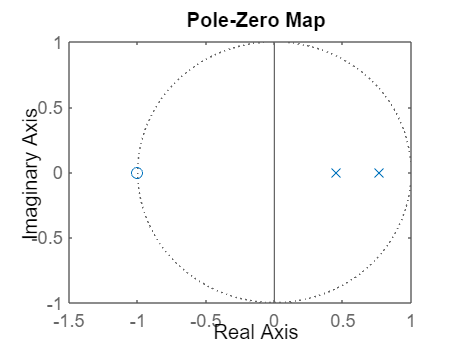


pzmap(Observer); 

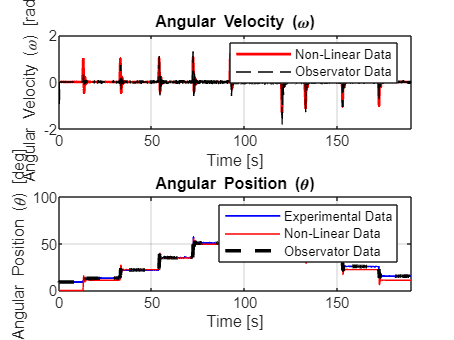


save('data/observer.mat',"L", "SysHat");
save('../implementacion/data/observer.mat', "L", "Observer"); 

addpath("sims/");
data = sim("sims/observer", 190); % Simulacion 

t = data.tout; 
% Velocities
omega = data.omega.Data ; 
omega_hat = data.omega_hat.Data;
omega_SS = data.omegaSS.Data;

% Angles 
theta = data.theta.Data ; 
theta_hat = data.theta_hat.Data ; 
theta_exp = data.theta_exp.Data; 
theta_SS = data.thetaSS.Data;

subplot(2, 1, 1); 
plot(t, omega,'r', "LineWidth",1.5)
hold on
plot(t, omega_hat, "k--", "LineWidth", 0.5); 
title("Angular Velocity (\omega)")
legend("Non-Linear Data", "Observator Data"); 
xlabel('Time [s]')
ylabel('Angular Velocity (\omega) [rad/s]')
xlim([0 190])
grid on; 

subplot(2, 1, 2); 
plot(DatosStepsVariables(:,1), DatosStepsVariables(:,3), 'b',"LineWidth", 1); 
hold on; 
plot(t, theta, 'r')
plot(t, theta_hat, "k--", "LineWidth", 2); 
hold off; 
title("Angular Position (\theta)")
xlabel('Time [s]')
xlim([0 190])
ylabel('Angular Position (\theta) [deg]')
legend("Experimental Data", "Non-Linear Data", "Observator Data" ); 
grid on; 



% subplot(4,1,3)
% plot(t, omega_hat, t, omega_SS, "r--", "LineWidth", 0.5); 
% subplot(4,1,4)
% plot(t,theta_hat,t,theta_SS, "r--", "LineWidth", 0.5)

## Gráfica

figure()
subplot(2,1,1)
plot(DatosStepsVariables(:,1), 100*DatosStepsVariables(:,2))
xlim([0 180]);
xl = xlabel('Time [s]')

xl =   Text (Time [s]) with properties:

                 String: 'Time [s]'
               FontSize: 9.9000
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [90.0001 -6.5642 -1]
                  Units: 'data'

  Show all properties


yl = ylabel('% PWM')

yl =   Text (% PWM) with properties:

                 String: '% PWM'
               FontSize: 9.9000
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [-7.9558 25.0000 -1]
                  Units: 'data'

  Show all properties


fontsize(yl,10,'points')
fontsize(xl,10,'points')
tit2 = title('Test Signal')

tit2 =   Text (Test Signal) with properties:

                 String: 'Test Signal'
               FontSize: 9.9000
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [90.0001 50.6913 0]
                  Units: 'data'

  Show all properties


grid on;
subplot(2,1,2)
plot(DatosStepsVariables(:,1), DatosStepsVariables(:,3), 'b',"LineWidth", 1); 
hold on; 
plot(t, theta, 'r')
hold off; 
xlim([0,200])
tit = title("Angular Position \theta")

tit =   Text (Angular Position \theta) with properties:

                 String: 'Angular Position \theta'
               FontSize: 9.9000
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [100.0001 101.3827 0]
                  Units: 'data'

  Show all properties


xl = xlabel('Time [s]')

xl =   Text (Time [s]) with properties:

                 String: 'Time [s]'
               FontSize: 9.9000
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [100.0001 -13.1285 -1]
                  Units: 'data'

  Show all properties


yl = ylabel('Angular Position [deg]')

yl =   Text (Angular Position [deg]) with properties:

                 String: 'Angular Position [deg]'
               FontSize: 9.9000
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [-11.7864 50.0000 -1]
                  Units: 'data'

  Show all properties


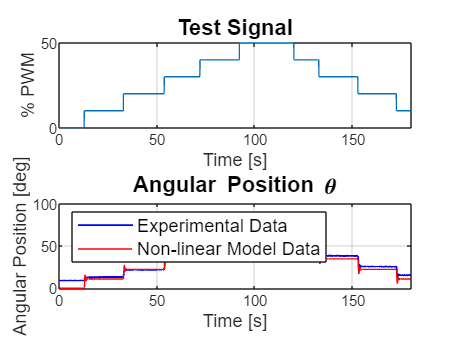

lgd = legend("Experimental Data", "Non-linear Model Data" ,'Location','northwest'); 
grid on;
xlim([0 180])
fontsize(yl,10,'points')
fontsize(xl,10,'points')
fontsize(lgd,10,'points')
fontsize(tit,12,'points')
fontsize(tit2,12,'points')

## Implementación Arduino

L

L = 1.0e+04 *

    0.0401
    3.0303


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



integrador =  1/s;
intDiscrete = c2d(integrador,2.5e-3,'tustin')

intDiscrete =
 
  0.00125 z + 0.00125
  -------------------
         z - 1
 
Sample time: 0.0025 seconds
Discrete-time transfer function.




sys

sys =
 
  A = 
            theta    omega
   theta        0        1
   omega  -0.8957   -3.334
 
  B = 
              u1
   theta       0
   omega  0.9745
 
  C = 
          theta  omega
   theta      1      0
 
  D = 
          u1
   theta   0
 
Continuous-time state-space model.



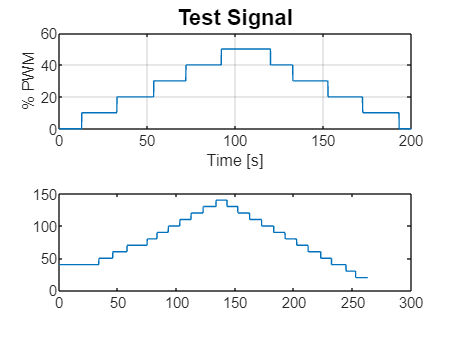

plot(DatosPID(:,1),DatosPID(:,4))